# Ejercicio 2

load('Tchaikovsky.mat','signal','Fs')
signal=signal(:,1)

signal =     0.0002
    0.0001
    0.0001
    0.0002
    0.0001
    0.0001
   -0.0001
   -0.0001
    0.0002
    0.0000


Fs

Fs = 44100

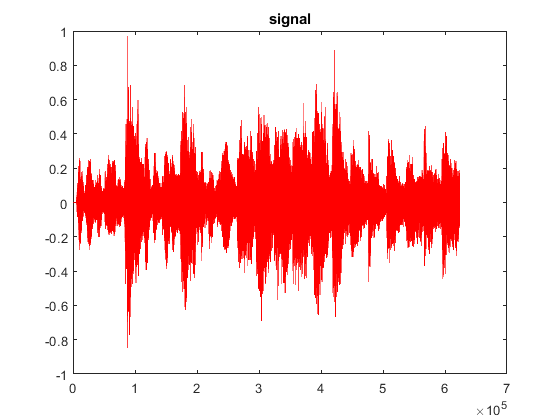

figure(1)
plot(signal,'r')
title('signal')
hold off

## 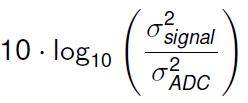

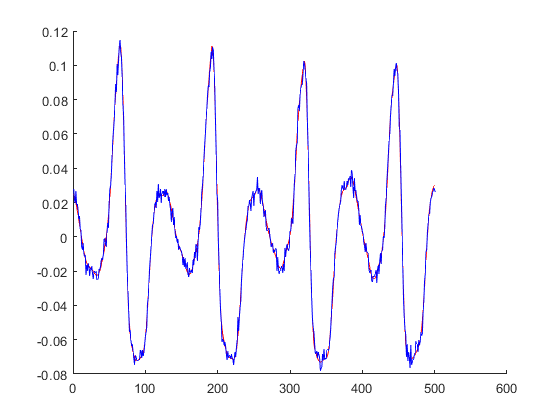

signal_with_noise=awgn(signal,50);
figure(2)
hold on
graph_in=7500;
graph_lim=8000;
plot(signal(graph_in:graph_lim),'r')
plot(signal_with_noise(graph_in:graph_lim),'b')
hold off

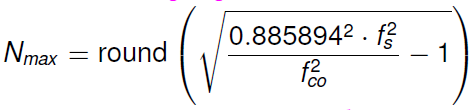

Con N mayores podés perder información importante en la señal al suavizarla. Se aproxima porque es entero.

fco=11025;
N_max=round(sqrt((0.885894*Fs/fco)^2-1))

N_max = 3

N=N_max;
fcoreal=0.885894*44100/sqrt(N^2+1)

fcoreal = 1.2354e+04

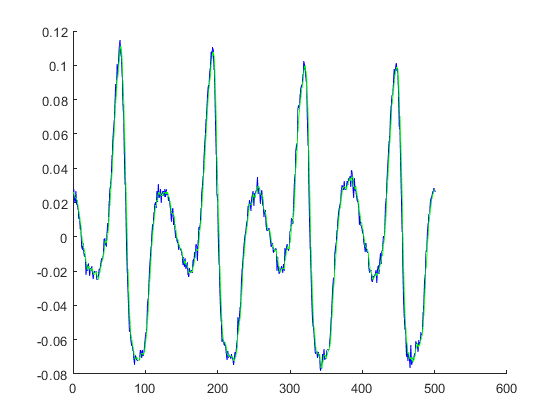

b=1/N*ones(1,N);
a=1;
signal_filtered=filter(b,a,signal_with_noise);
figure(3)
hold on
plot(signal_with_noise(graph_in:graph_lim),'b')
plot(signal_filtered(graph_in:graph_lim),'g')
hold off

sound(signal,Fs)

Podemos notar la señal sin ruido con claridad

sound(signal_with_noise,Fs)

Podemos notar un ruido de interferencia

sound(signal_filtered,Fs)

Podemos notar una interferencia mucho menor

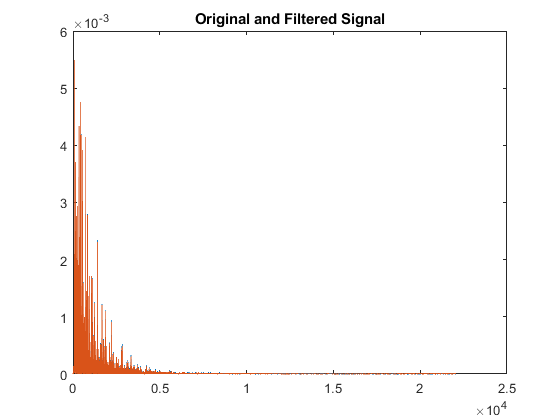

addpath('m-files\')

[f, dft_mag, dft_phase, dft, NFFT] = my_dft(signal, Fs);
figure(4)
plot(f,dft_mag)
title('Original and Filtered Signal')
hold on
[f2, dft_mag2, dft_phase, dft, NFFT] = my_dft(signal_filtered, Fs);
plot(f2,dft_mag2)
hold off

## N=N_max/2

N=round(N_max/2)

N = 2

fcoreal=0.885894*44100/sqrt(N^2+1)

fcoreal = 1.7472e+04

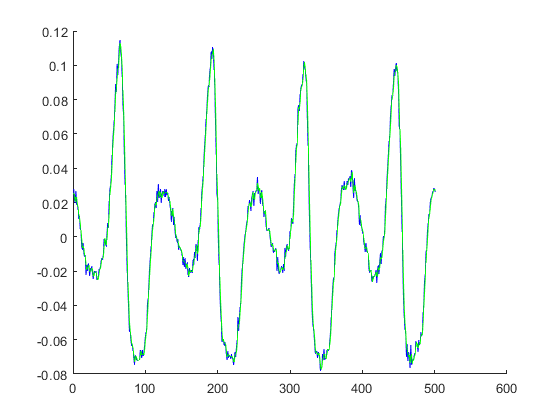

b=1/N*ones(1,N);
a=1;
signal_filtered=filter(b,a,signal_with_noise);
figure(6)
hold on
plot(signal_with_noise(graph_in:graph_lim),'b')
plot(signal_filtered(graph_in:graph_lim),'g')
hold off

sound(signal_filtered,Fs)

Ruido aumentó

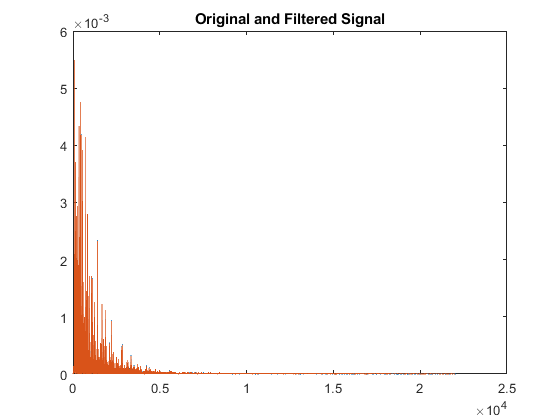

[f, dft_mag, dft_phase, dft, NFFT] = my_dft(signal, Fs);
figure(7)
plot(f,dft_mag)
title('Original and Filtered Signal')
hold on
[f2, dft_mag2, dft_phase, dft, NFFT] = my_dft(signal_filtered, Fs);
plot(f2,dft_mag2)
hold off

## N=10*N_max

N=N_max*10

N = 30

fcoreal=0.885894*44100/sqrt(N^2+1)

fcoreal = 1.3015e+03

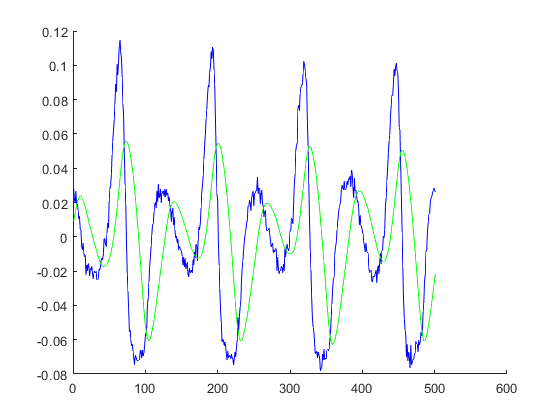

b=1/N*ones(1,N);
a=1;
signal_filtered=filter(b,a,signal_with_noise);
figure(9)
hold on
plot(signal_with_noise(graph_in:graph_lim),'b')
plot(signal_filtered(graph_in:graph_lim),'g')
hold off

La señal se atrasa al tener que promediar más valores. El impacto de una subida tarda en impactar en la señal promediada.

sound(signal_filtered,Fs)

Se apaga la señal ppal, al estar recortando ya frecuencias que aportaban información

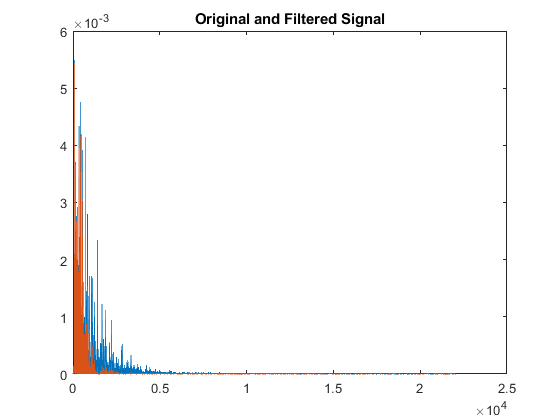

[f, dft_mag, dft_phase, dft, NFFT] = my_dft(signal, Fs);
figure(10)
plot(f,dft_mag)
title('Original and Filtered Signal')
hold on
[f2, dft_mag2, dft_phase, dft, NFFT] = my_dft(signal_filtered, Fs);
plot(f2,dft_mag2)
hold off